# APROKSYMACJA

## IMPLEMENTACJE APROKSYMACJI

Aproksymacja wielomianowa, o której mówimy może być zaimplementowana na dwa sposoby:

1. Pierwszy sposób polega na tym, że tworzymy macierz nadokreślonego układu równań, którą następnie rozwiązujemy za pomocą metod rozwiązania Liniowego Zadania Najmniejszych Kwadratów

% wytwórzmy przykładowe punkty do obliczenia aproksymacji
N = 20;                % 20 węzłów
M = 6;                 % wielomian stopnia 6
xx=linspace(1, 10, N); 
fun = @(x) x.^6./exp(x);
yy = fun(xx);   

% Uruchommy drugą implementację aproksymacji
[wsp, S] = polyfit(xx,yy,M);       %aproksymujemy za pomocą wielomianu 6 stopnia

%Zanim narysujemy wynik aproksymacji przyjrzyjmy się strukturze S
%Tutaj znajduje się norma residuów w węzłach
fprintf("Implementacja 1\n");

Implementacja 1


fprintf("Norma residuów: %e",S.normr);

Norma residuów: 2.358427e+00

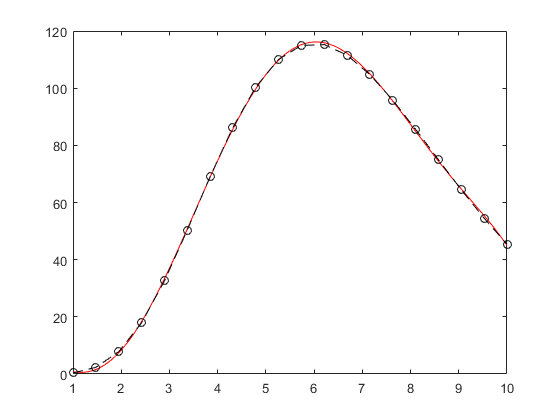


%Wyrysujmy wynik
x=linspace(min(xx), max(xx), 401);
y = polyval(wsp,x);
plot(x, y, 'r', xx,yy,'ko', xx,fun(xx), 'k--')

2. Druga implementacja polega na rozwiązaniu układu równań zbudowanego z iloczynów skalarnych. Realizuje ją poniższy kod - przyjrzyj się na czym polega istota tej metody

% Uruchommy drugą implementację aproksymacji
[wsp, normr] = dotProductApproximation(xx,yy,M);       %aproksymujemy za pomocą wielomianu 6 stopnia

%Zanim narysujemy wynik aproksymacji przyjrzyjmy się strukturze S
%Tutaj znajduje się norma residuów w węzłach
fprintf("Implementacja 2\n");

Implementacja 2


fprintf("Norma residuów: %e\n",normr);

Norma residuów: 2.358427e+00



%Wyrysujmy wynik
x=linspace(min(xx), max(xx), 401);
y = polyval(wsp,x);
plot(x, y, 'r', xx,yy,'ko', xx,fun(xx), 'k--')

Pozornie te dwa sposoby są identyczne, ale sposób drugi (równania normalne) jest w rzeczywistości mniej stabilny numerycznie od sposobu pierwszego, opartego o rozkład SVD wewnątrz funkcji `polyfit`.

**ĆWICZENIE 1**

Manipulując ilością węzłów oraz stopniem wielomianu interpolującego spróbuj dobrać takie warunki, w których sposób 2 będzie lepszy od sposobu 1. Obserwuj zauważalne różnice w trakcie tego eksperymentu. Zapisz sobie jakie ustawienia testowałeś i jaka była norma residuów dla danego ustawienia.

**ĆWICZENIE 2**

Na efekt aproksymacji wpływ mają nie tylko właściwości układu równań, ale również właściwości funkcji wewnątrz przedziału aproksymacji. Powtórz poprzedni eksperyment dla przedziału [1,2]. Sprawdź czy widać znaczne różnice między wynikami z ćwiczenia 1 i ćwiczenia 2.

## WYKORZYSTYWANE FUNKCJE

function [wsp, normr, Fi, A] = dotProductApproximation(xx,yy,n)
    N=n+1;
    %Budujemy macierz Fi dla prostej bazy wielomianowej
    for i=1:1:N
        for j=1:1:numel(xx)
            Fi(j,i)=polyval(eye(1,i),xx(j));
        end
    end
    %Obliczamy macierz transponowaną
    FiT = Fi';
    %Obliczamy macierz A układu równań
    A= FiT*Fi;
    %Obliczamy wektor b
    for i=1:1:N
        b(i)=dot(polyval(eye(1,i),xx),yy);
    end
    %Obliczamy rozwiązanie
    wsp = A\b';wsp=flip(wsp);
 
    normr = norm(polyval(wsp,xx)-yy);
end